# German Tweet Sentiment Dataset (Multilingual E5 large)

## Setup

clc;
clear all;
close all;
rng(1634256, "twister");

addpath(genpath(fileparts(which(mfilename))));

## Load Data

% Import the data
rawData = parquetread("./datasets/tweet_sentiment_multilingual/tweet_sentiment_multilingual_de_multilingual-e5-large.parquet", "SelectedVariableNames", ["text", "label", "embedding"]);

rawData.label = categorical(rawData.label, [0,1,2], {'negative' 'neutral' 'positive'});

rawData(1:8, :)

ans = 8×3 table
                                                                    text                                                                      label         embedding   
    _____________________________________________________________________________________________________________________________________    ________    _______________

    "Normal bin ich ja ned der mensch dwer sich beschwert wegen dem essen aber diese Pizza von Joeys...boah wie ekelhaft"                    negative    {1024×1 single}
    "VfB Stuttgart gegen SV Hamburg: Das Warten auf den nächsten Schritt - Stuttgarter Zeitung: DIE WELTVfB Stuttga... http"                 neutral     {1024×1 single}
    "@user @user @user @user @user @user @user @user fühlt sich schon so spät an 😚😚😚"                                                     positive    {1024×1 single}
    "@user glaub ich! XD 30€ sind echt 

groupcounts(rawData, "label")

ans = 3×3 table
     label      GroupCount    Percent
    ________    __________    _______

    negative       613        33.333 
    neutral        613        33.333 
    positive       613        33.333 


## Preperation

contamination =0.25;

positiveIndices = find(rawData.label == "positive");
negativeIndices = find(rawData.label == "negative");

numPositiveSamples = sum(rawData.label == "positive");
numNegativeSamples = round(numPositiveSamples * (1 + contamination) * contamination);

negativeSampleIndices = datasample(negativeIndices, numNegativeSamples, "Replace", false);
positiveSampleIndices = datasample(positiveIndices, numPositiveSamples, "Replace", false);
data = rawData(sort(cat(1, positiveSampleIndices, negativeSampleIndices)),:);

clear positiveIndices;
clear negativeIndices;
clear numNegativeSamples;
clear numPositiveSamples;
clear negativeSampleIndices;
clear positiveSampleIndices;
clear rawData;

data.label = removecats(data.label);
groupcounts(data, "label")

ans = 2×3 table
     label      GroupCount    Percent
    ________    __________    _______

    negative       192        23.851 
    positive       613        76.149 


unlabeledData = cell2mat(cellfun(@transpose,data.embedding,'UniformOutput',false));
centredData = rZscores(unlabeledData);
labels = renamecats(data.label, {'positive' 'negative'}, {'inlier' 'outlier'});

## Separability

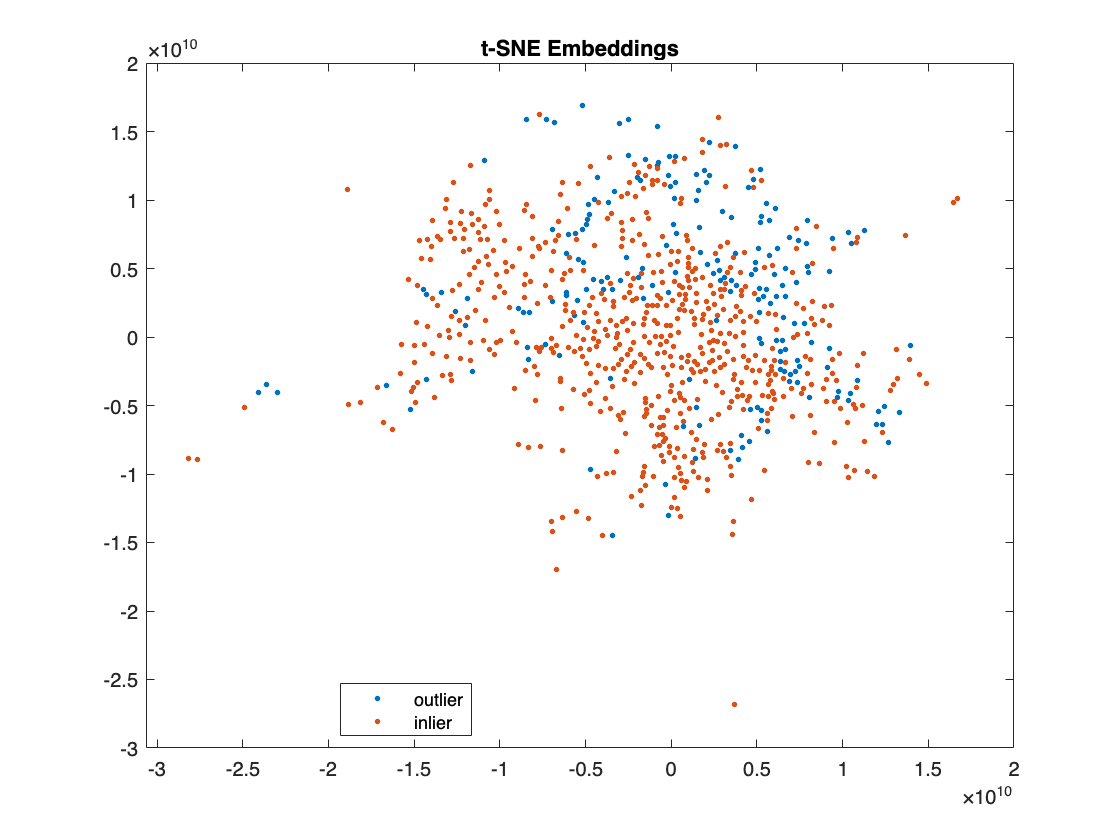

Y = tsne(unlabeledData, Distance="cosine");

figure;
gscatter(Y(:,1),Y(:,2),labels);
title("t-SNE Embeddings");

clear Y;

separabilityindex(unlabeledData, labels, Distance="cosine")

ans = 0.8099

distanceseparabilityindex(unlabeledData, labels, Distance="cosine")

## Computation

alpha = 0.6;
% kModel = AutoRbfKernel(centredData);
kModel = AutoSphereRbfKernel(unlabeledData);

AutoSphereRbfKernel: Sigma = 0.598709308278869


poc = kMRCD(kModel); 
% solution = poc.runAlgorithm(centredData, alpha);
solution = poc.runAlgorithm(unlabeledData, alpha);

Convergence at iteration 1, SDO
Convergence at iteration 1, SpatialRank
Convergence at iteration 1, SpatialMedian
Convergence at iteration 1, SSCM
-> Best estimator is SSCM


## Evaluation

hSubset = data(solution.hsubsetIndices, :);

groupcounts(hSubset, "label")

ans = 2×3 table
     label      GroupCount    Percent
    ________    __________    _______

    negative        95        19.669 
    positive       388        80.331 


outliers = data(solution.flaggedOutlierIndices, :);

groupcounts(outliers, "label")

ans = 2×3 table
     label      GroupCount    Percent
    ________    __________    _______

    negative        97        30.124 
    positive       225        69.876 


### Confusion Matrix

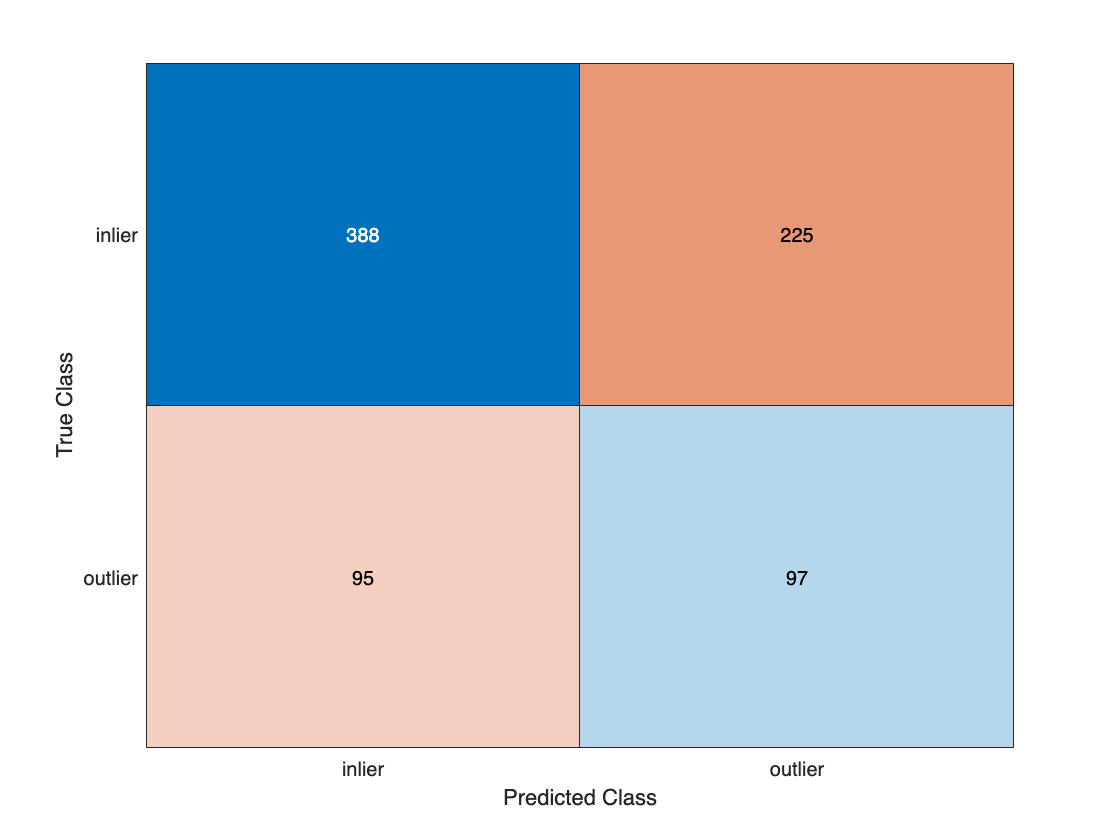

grouphat = categorical(repmat("inlier", [size(data,1),1]), categories(labels));
grouphat(solution.flaggedOutlierIndices) = "outlier";

cm = confusionmat(labels,grouphat);
figure;
confusionchart(cm, categories(labels));

struct2table(confusionstats(cm))

ans = 1×5 table
    accuracy    precision    sensitivity    specificity    f1Score
    ________    _________    ___________    ___________    _______

    0.60248      0.80331       0.63295        0.50521      0.70803


### Mahalanobis Distances

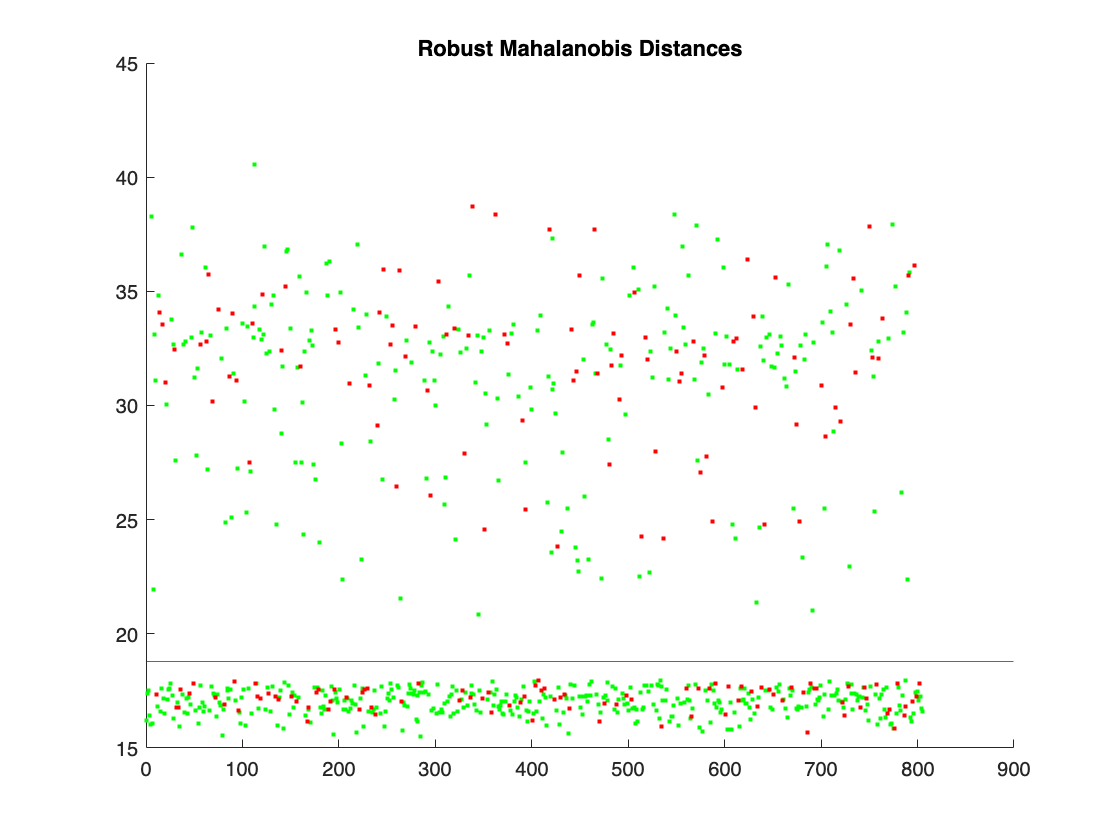

figure;
mahalchart(labels, solution.rd, solution.cutoff);

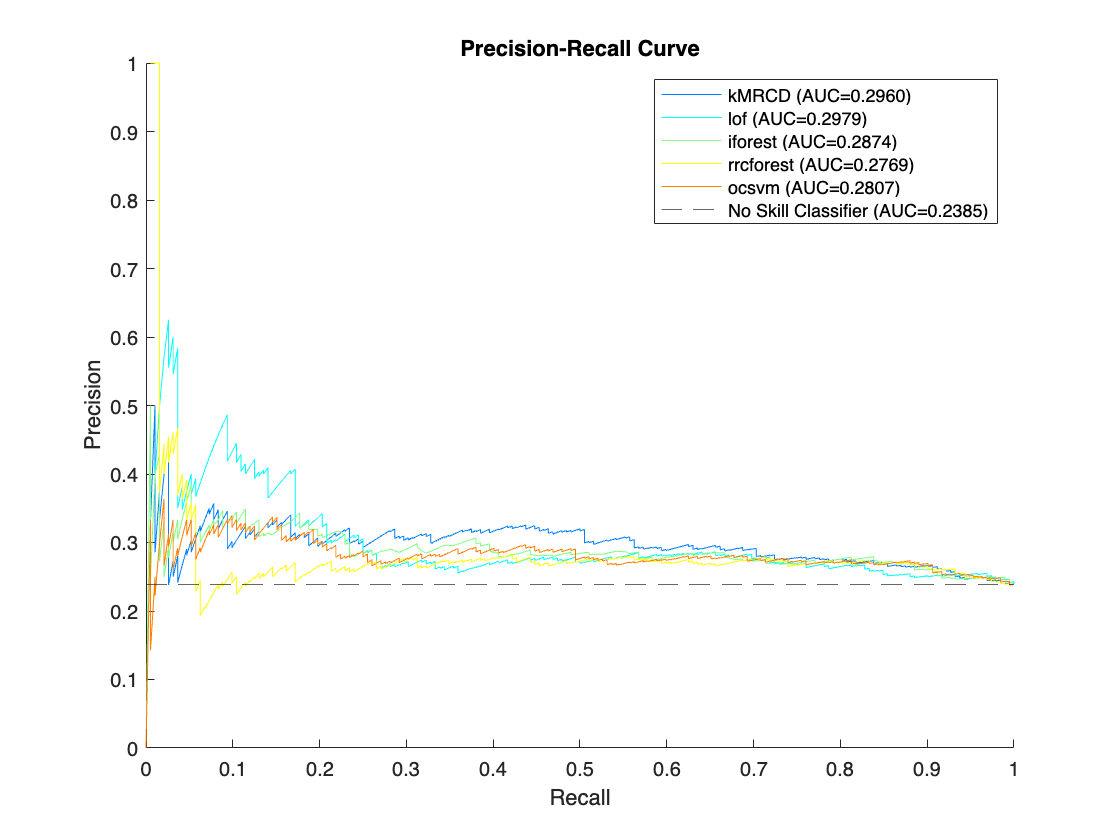

ans = 5×6 table
                 accuracy    precision    sensitivity    specificity    f1Score     aucpr 
                 ________    _________    ___________    ___________    _______    _______

    kMRCD        0.60248      0.80331       0.63295        0.50521      0.70803    0.29602
    lof          0.58261      0.78675        0.6199        0.46354      0.69343    0.29789
    iforest      0.58509      0.78882       0.62153        0.46875      0.69526    0.28737
    rrcforest    0.57764      0.78261       0.61664        0.45312      0.68978     0.2769
    ocsvm        0.59255      0.79503       0.62643        0.48438      0.70073    0.28073


evaluation(unlabeledData, labels, alpha, solution)

Convergence at iteration 1, SDO
Convergence at iteration 1, SpatialRank
Convergence at iteration 1, SpatialMedian
Convergence at iteration 1, SSCM
-> Best estimator is SSCM
Convergence at iteration 1, SDO
Convergence at iteration 1, SpatialRank
Convergence at iteration 1, SpatialMedian
Convergence at iteration 1, SSCM
-> Best estimator is SSCM
Convergence at iteration 1, SDO
Convergence at iteration 1, SpatialRank
Convergence at iteration 1, SpatialMedian
Convergence at iteration 1, SSCM
-> Best estimator is SSCM
Convergence at iteration 1, SDO
Convergence at iteration 1, SpatialRank
Convergence at iteration 1, SpatialMedian
Convergence at iteration 1, SSCM
-> Best estimator is SSCM
Convergence at iteration 1, SDO
Convergence at iteration 1, SpatialRank
Convergence at iteration 1, SpatialMedian
Convergence at iteration 1, SSCM
-> Best estimator is SSCM
Convergence at iteration 1, SDO
Convergence at iteration 1, SpatialRank
Convergence at iteration 1, SpatialMedian
Convergence at iterat

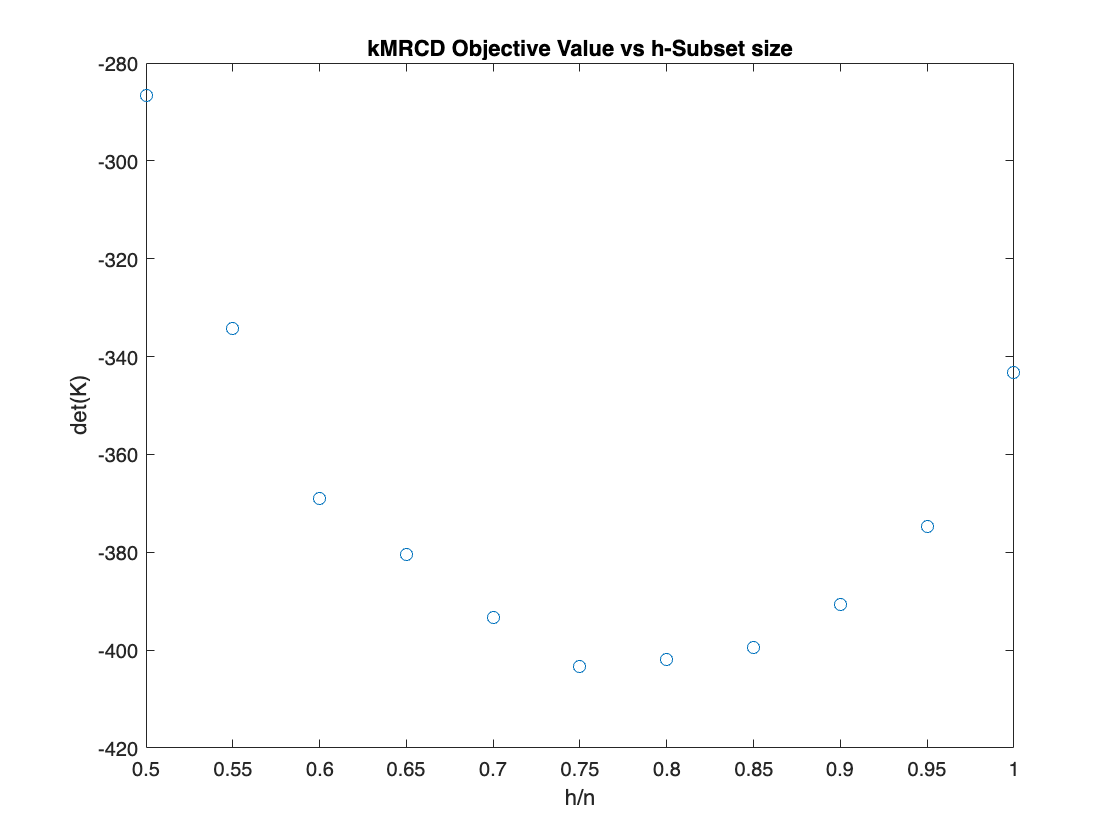

% objectiveplot(poc, centredData);
objectiveplot(poc, unlabeledData);